# **LAB 3. Synchronous motor drive modelling**

Tmdl = 0.0004;
load("var_94.mat");
modelName = 'lab3s.slx'

modelName = 'lab3s.slx'

3. Assemble a mathematical model of a synchronous machine in the rotor coordinate  system dq in Matlab/Simulink.

Tmdl = 1;
const = 1;
w0 = 0.1;
u0 = 1;
um = 1;
Tmax = 3/2*Zp*Psif/R*Udc/2*u0; 
Trate = Tmax/Tmdl;  %Tdist

Tq = L/R;
T_T = 0.001;
kp = R*Trate/T_T;
ki = R/T_T;
km = 3/2*Zp*Psif

km = 3

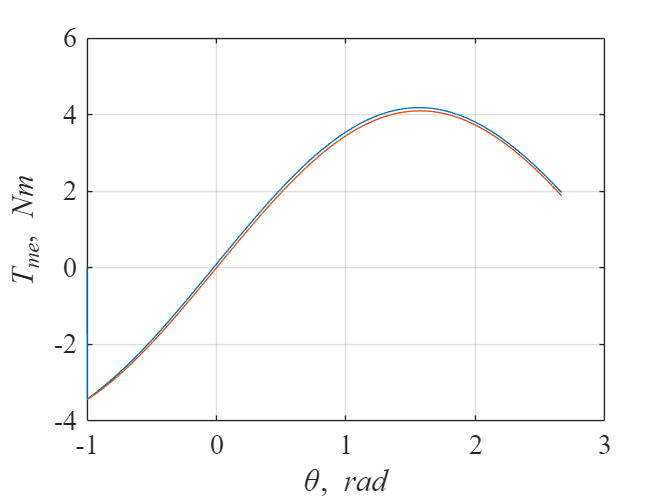


warning off
SimOut = sim('lab3s.slx', 'ReturnWorkspaceOutputs', 'on');
warning on
Tme = SimOut.yout{1}.Values.Data(:,1);
theta = SimOut.yout{1}.Values.Data(:,2);
h = figure;
    set(h,'DefaultAxesFontSize',14);
    set(h,'DefaultAxesFontName','Times New Roman');
    plot(theta,Tme)
    grid on
    hold on
    plot(theta,Tmax*sin(theta))
    xlabel('\theta, \itrad')
    ylabel('\itT_m_e\rm, \itNm')     

4

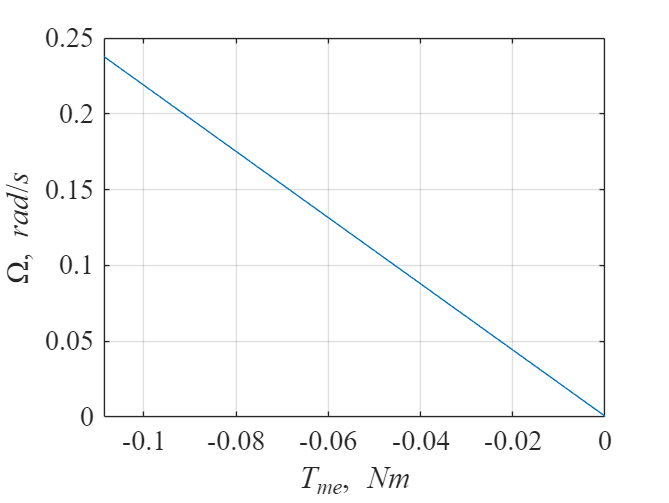

Tmax = 3/2*Zp*Psif/R*Udc/2*u0;
Trate = Tmax/Tmdl; 
warning off 
warning on
t = SimOut.yout{2}.Values.Time;
Tme = SimOut.yout{2}.Values.Data(:,1);
Om = SimOut.yout{2}.Values.Data(:,2);
h = figure;
    set(h,'DefaultAxesFontSize',14);
    set(h,'DefaultAxesFontName','Times New Roman');
    plot(Tme,Om)
    grid on
    hold on
    ylabel('\Omega, \itrad\rm/\its')
    xlabel('\itT_m_e\rm, \itNm')

5

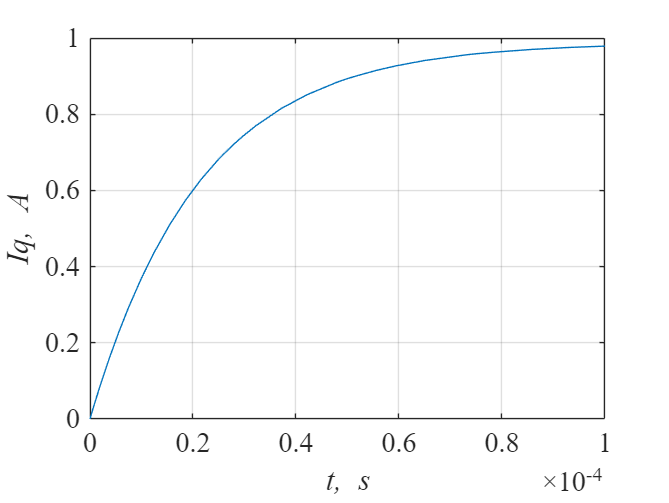

Tq = L/R;
T_T = 0.05;
kp = R*Trate/T_T;
ki = R/T_T;
Tmdl = 0.0001;

warning off
SimOut = sim('lab3s.slx', 'ReturnWorkspaceOutputs', 'on');
warning on

t = SimOut.yout{3}.Values.Time;
Iq = SimOut.yout{3}.Values.Data(:,1);
h = figure;
    set(h,'DefaultAxesFontSize',14);
    set(h,'DefaultAxesFontName','Times New Roman');
    plot(t,Iq)
    grid on
    ylabel('\itIq, \itA')
    xlabel('\itt, \its')

T_T

T_T = 0.0500

Tq

Tq = 0.0018

kp

kp = 1440

ki

ki = 351.3304

km = 3/2*Zp*Psif

km = 3

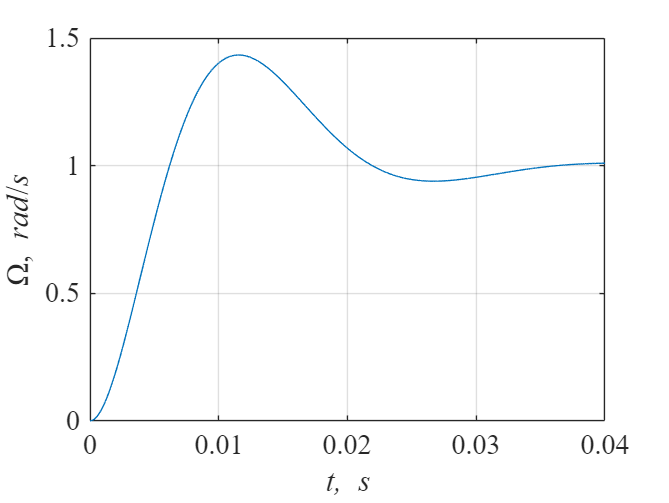

T_T = 0.002;
kp = J/2/T_T/km;
ki = J/8/T_T^2/km;

Tmdl = 0.04;

warning off
SimOut = sim('lab3s.slx', 'ReturnWorkspaceOutputs', 'on');
warning on

t = SimOut.yout{4}.Values.Time;
Omega = SimOut.yout{4}.Values.Data(:,1);
h = figure;
    set(h,'DefaultAxesFontSize',14);
    set(h,'DefaultAxesFontName','Times New Roman');
    plot(t,Omega)
    grid on
    ylabel('\Omega, \itrad\rm/\its')
    xlabel('\itt, \its')


T_T

T_T = 0.0020

km

km = 3

Tq

Tq = 0.0018

kp

kp = 331.1515

ki

ki = 4.1394e+04